#### Wymagane toolbox'y:

- Mapping Toolbox

#### Makra

function maxs = avg_maximums_month(tables)
    maxs = zeros(length(tables), 12);

    for i = 1:length(tables)
        table = tables{i};

        for j = 1:12
            maxs(i, j) = round(mean(table(month(table.date) == j, "max_temp").max_temp), 1);
        end
    end
end

function mins = avg_minimums_month(tables)
    mins = zeros(length(tables), 12);

    for i = 1:length(tables)
        table = tables{i};

        for j = 1:12    
            mins(i, j) = round(mean(table(month(table.date) == j, "min_temp").min_temp), 1);
        end
    end
end

function maxs = avg_maximums_day(table)
    maxs = zeros(1, 365);
    table = table(~(month(table.date) == 2 & day(table.date) == 29), :);

    for i = 1:365
        maxs(i) = round(mean(table(day(table.date, 'dayofyear') == i, "max_temp").max_temp), 1);
    end
end

function mins = avg_minimums_day(table)
    mins = zeros(1, 365);
    table = table(~(month(table.date) == 2 & day(table.date) == 29), :);

    for i = 1:365
        mins(i) = round(mean(table(day(table.date, 'dayofyear') == i, "min_temp").min_temp), 1);
    end
end

#### Wczytanie danych z plików CSV

brazil_curitiba = readtable("brazil_curitiba.csv");
colombia_medellin = readtable("colombia_medellin.csv");
brazil_natal = readtable("brazil_natal.csv");
brazil_portoalegre = readtable("brazil_porto-alegre.csv");
ecuador_quito = readtable("ecuador_quito.csv");
brazil_saopaulo = readtable("brazil_sao-paulo.csv");

datasources = {brazil_curitiba, colombia_medellin, brazil_natal, brazil_portoalegre, ecuador_quito, brazil_saopaulo};

#### Pokazanie na mapie miejsc, których dotyczą nasze dane

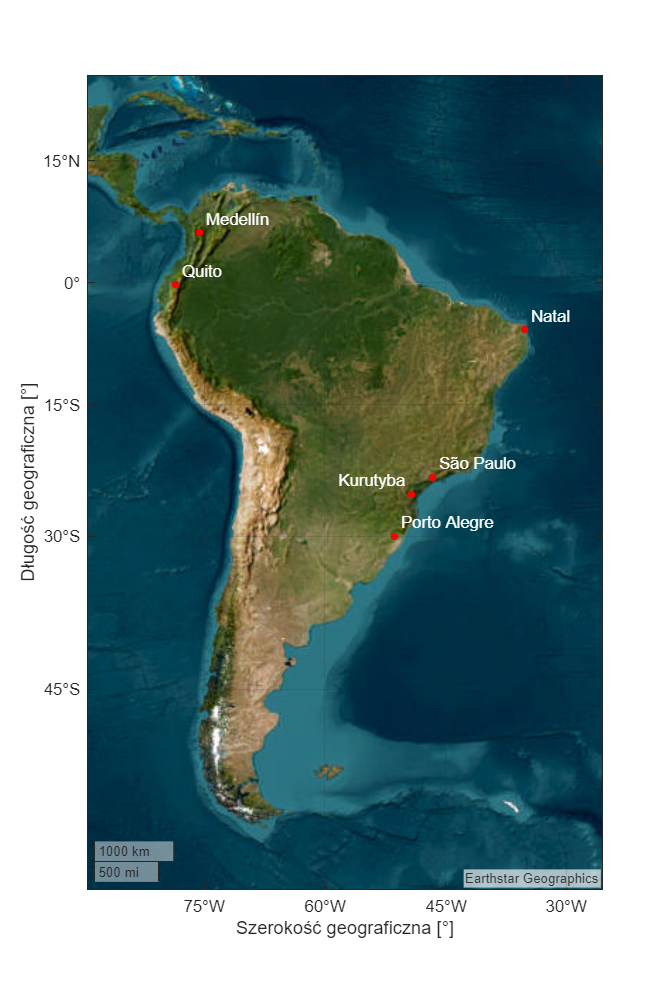

cities = {'Kurutyba', 'Medellín', 'Natal', 'Porto Alegre', 'Quito', 'São Paulo'};
latitudes = [-25.468611, 6.216667, -5.795, -30.039444, -0.25, -23.5];
longitudes = [-49.253333, -75.566667, -35.208889, -51.307778, -78.583333, -46.616667];

figure(1);
set(gcf, 'Position', [100, 100, 800, 1200]);
geobasemap('satellite');
hold on;

geolimits([-60, 25], [-85, -30]);
geoscatter(latitudes, longitudes, 20, 'red', 'filled');

for i = 1:length(cities)
    x = 0.8;
    y = 0.5;
    ha = 'left';

    if strcmp(cities{i}, 'Kurutyba')
        x = -0.8;
        ha = 'right';
    end

    text(latitudes(i) + y, longitudes(i) + x, cities{i}, ...
        'FontSize', 10, 'Color', 'white', ...
        'HorizontalAlignment', ha, 'VerticalAlignment', 'bottom');
end

gx = gca;
gx.LatitudeLabel.String = 'Długość geograficzna [°]';
gx.LongitudeLabel.String = 'Szerokość geograficzna [°]';

hold off;

#### Porównanie średnichm, maksymalnych i minimalnych temperatur w każdym mieście dla poszczególnych miesięcy

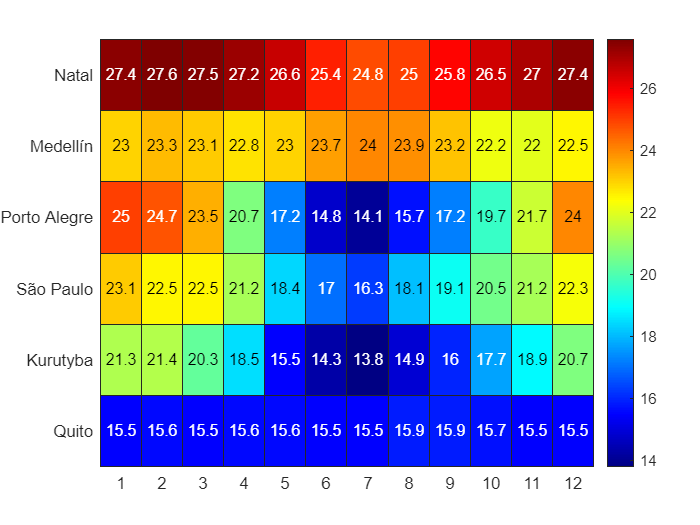

averages_table = readtable("averages.csv", "VariableNamesLine", 1, "ReadRowNames", true);
averages_table = averages_table([3, 2, 4, 6, 1, 5], :);

figure(2);
heatmap(1:12, averages_table.city, averages_table.Variables);
colormap(jet);

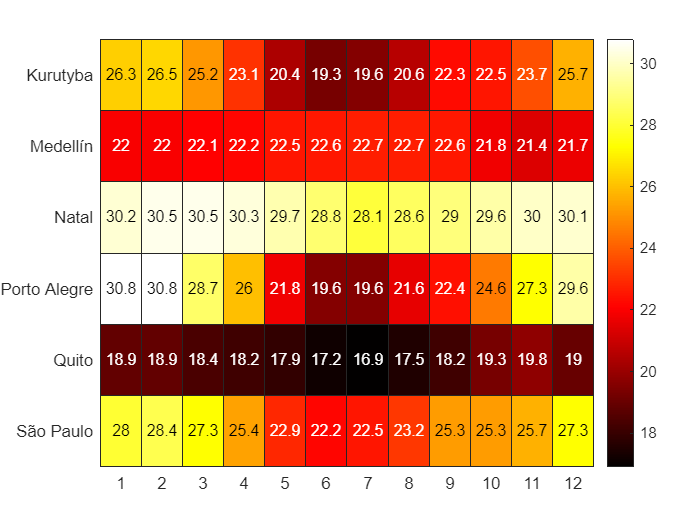

maximums_table = avg_maximums_month({brazil_curitiba, colombia_medellin, brazil_natal, brazil_portoalegre, ecuador_quito, brazil_saopaulo});

figure(3);
heatmap(1:12, cities, maximums_table);
colormap(hot);

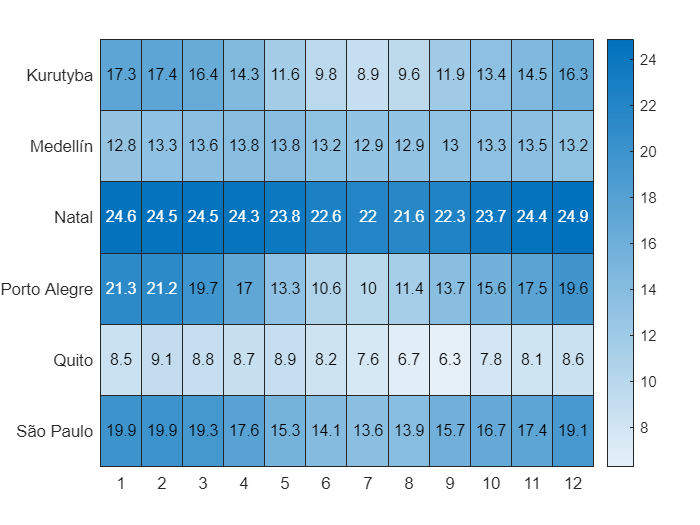

minimums_table = avg_minimums_month({brazil_curitiba, colombia_medellin, brazil_natal, brazil_portoalegre, ecuador_quito, brazil_saopaulo});

figure(4);
heatmap(1:12, cities, minimums_table);

#### Zestawienie maksymalnych i minimalnych temperatur w każdym mieście dla poszczególnych dni na wykresie biegunowym

Warto zaznaczyć: w zestawie danych pojawiają się dni przestępne 29 lutego. Zatem aby wyrównać lata przestępne ze zwykłymi, pominiemy ten dzień, jeśli się pojawi.

theta = linspace(0, 2*pi, 366);
theta_smooth = linspace(0, 2*pi, 1000);

maximums_render = cell(1, length(datasources));

for i = 1:length(datasources)
    avgs_max = avg_maximums_day(datasources{i});
    smooth = smoothdata(avgs_max, 'gaussian', 14);
    smooth_closed = [smooth, smooth(1)];
    interp = interp1(theta, smooth_closed, theta_smooth, 'spline');
    maximums_render{i} = interp;
end

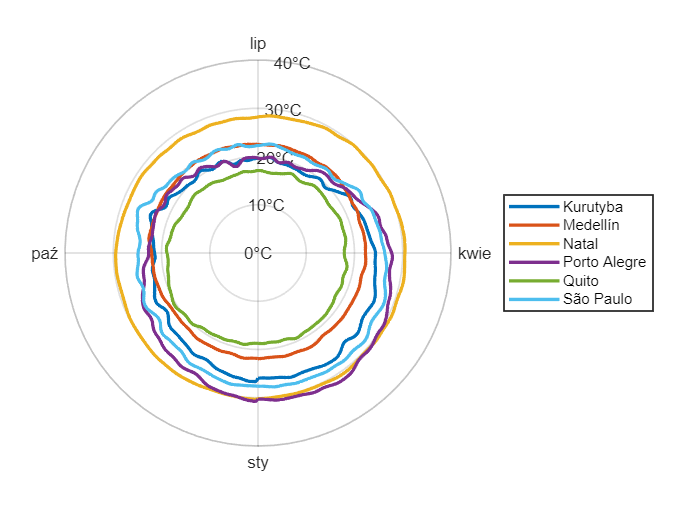

figure(5); clf;
pax = polaraxes;
hold(pax, 'on');

for i = 1:length(maximums_render)
    polarplot( ...
        theta_smooth, maximums_render{i}, ...
        'LineWidth', 2 ...
    );
end

ax = gca;
ax.LineWidth = 1;
ax.RLim = [0 40];
ax.RTick = 0:10:40;
ax.RTickLabel = arrayfun(@(x) sprintf('%.0f°C', x), ax.RTick, 'UniformOutput', false); % Add °C to radial tick labels
ax.ThetaZeroLocation = 'bottom';
ax.ThetaTick = [0 90 180 270];
ax.ThetaTickLabel = {'sty', 'kwie', 'lip', 'paź'};
%ax.RAxis.Label.String = 'Temperatura [℃]';
%ax.RAxis.Label.Position = [5 0 0];
%ax.ThetaAxis.Label.String = 'Data';


legend(cities);

hold(pax, 'off');

theta = linspace(0, 2*pi, 366);
theta_smooth = linspace(0, 2*pi, 1000);

minimums_render = cell(1, length(datasources));

for i = 1:length(datasources)
    avgs_min = avg_minimums_day(datasources{i});
    smooth = smoothdata(avgs_min, 'gaussian', 14);
    smooth_closed = [smooth, smooth(1)];
    interp = interp1(theta, smooth_closed, theta_smooth, 'spline');
    minimums_render{i} = interp;
end

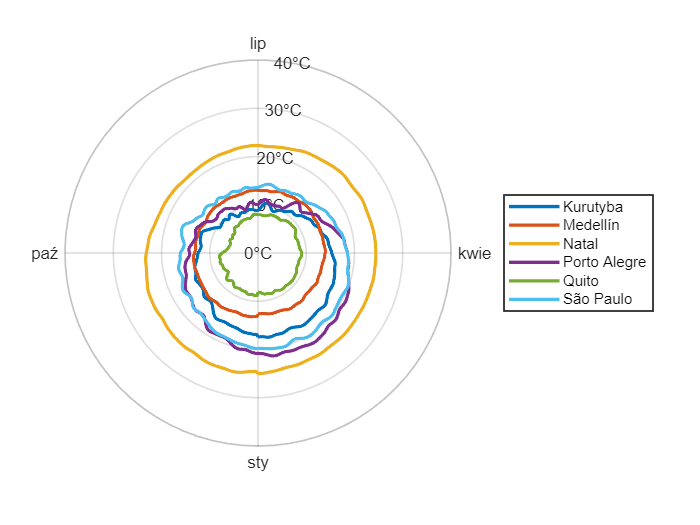

figure(6); clf;
pax = polaraxes;
hold(pax, 'on');

for i = 1:length(minimums_render)
    polarplot( ...
        theta_smooth, minimums_render{i}, ...
        'LineWidth', 2 ...
    );
end

ax = gca;
ax.LineWidth = 1;
ax.RLim = [0 40];
ax.RTick = 0:10:40;
ax.RTickLabel = arrayfun(@(x) sprintf('%.0f°C', x), ax.RTick, 'UniformOutput', false); % Add °C to radial tick labels
ax.ThetaZeroLocation = 'bottom';
ax.ThetaTick = [0 90 180 270];
ax.ThetaTickLabel = {'sty', 'kwie', 'lip', 'paź'};
%ax.RAxis.Label.String = 'Temperatura [℃]';
%ax.RAxis.Label.Position = [5 0 0];
%ax.ThetaAxis.Label.String = 'Data';


legend(cities);

hold(pax, 'off');

#### Porównanie minimalnych i maksymalnych temperatur w ciągu roku pomiędzy Sao Paulo a Medellin

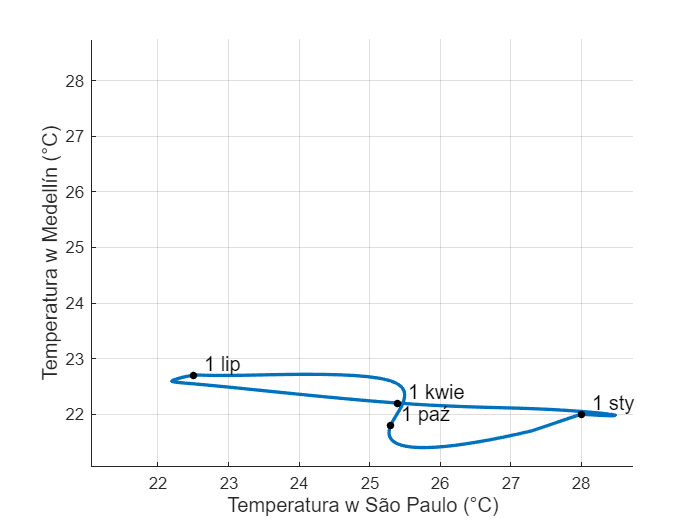

t = 1:12;
ts = 1:0.1:12;

maximums_cm_o = avg_maximums_month({colombia_medellin});
maximums_bs_o = avg_maximums_month({brazil_saopaulo});

min_temp = min([maximums_bs_o, maximums_cm_o]);
max_temp = max([maximums_bs_o, maximums_cm_o]);

maximums_cm = interp1(t, maximums_cm_o, ts, 'spline');
maximums_bs = interp1(t, maximums_bs_o, ts, 'spline');

maximums_cm = [maximums_cm, maximums_cm(1)];
maximums_bs = [maximums_bs, maximums_bs(1)];

padding = 0.05 * (max_temp - min_temp);
min_limit = min_temp - padding;
max_limit = max_temp + padding;

figure(7); clf;
hold on;

plot(maximums_bs, maximums_cm, 'LineWidth', 2);
xlim([min_limit max_limit]);
ylim([min_limit max_limit]);
grid on;

months_to_mark = [1, 4, 7, 10];
for i = months_to_mark
    idx = (i-1)*10 + 1; % Index in the smooth array corresponding to month i
    plot(maximums_bs_o(i), maximums_cm_o(i), 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 4);
    
    % Add month labels
    month_names = {'1 sty', '1 kwie', '1 lip', '1 paź'};
    text(maximums_bs_o(i) + 0.15, maximums_cm_o(i) + 0.20, month_names{months_to_mark==i}, 'FontSize', 12);
end

ylabel('Temperatura w Medellín (°C)', 'FontSize', 12);
xlabel('Temperatura w São Paulo (°C)', 'FontSize', 12);

hold off;

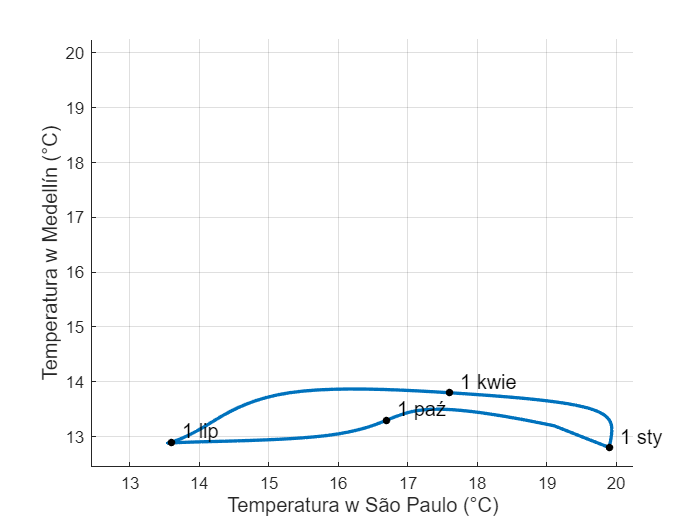

t = 1:12;
ts = 1:0.1:12;

minimums_cm_o = avg_minimums_month({colombia_medellin});
minimums_bs_o = avg_minimums_month({brazil_saopaulo});

min_temp = min([minimums_bs_o, minimums_cm_o]);
max_temp = max([minimums_bs_o, minimums_cm_o]);

minimums_cm = interp1(t, minimums_cm_o, ts, 'spline');
minimums_bs = interp1(t, minimums_bs_o, ts, 'spline');

minimums_cm = [minimums_cm, minimums_cm(1)];
minimums_bs = [minimums_bs, minimums_bs(1)];

padding = 0.05 * (max_temp - min_temp);
min_limit = min_temp - padding;
max_limit = max_temp + padding;

figure(8); clf;
hold on;

plot(minimums_bs, minimums_cm, 'LineWidth', 2);
xlim([min_limit max_limit]);
ylim([min_limit max_limit]);
grid on;

months_to_mark = [1, 4, 7, 10];
for i = months_to_mark
    idx = (i-1)*10 + 1; % Index in the smooth array corresponding to month i
    plot(minimums_bs_o(i), minimums_cm_o(i), 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 4);
    
    % Add month labels
    month_names = {'1 sty', '1 kwie', '1 lip', '1 paź'};
    text(minimums_bs_o(i) + 0.15, minimums_cm_o(i) + 0.20, month_names{months_to_mark==i}, 'FontSize', 12);
end

ylabel('Temperatura w Medellín (°C)', 'FontSize', 12);
xlabel('Temperatura w São Paulo (°C)', 'FontSize', 12);

hold off;

#### Porównanie maksymalnych temperatur w poszczególnych dniach roku pomiędzy Sao Paulo a Medellin

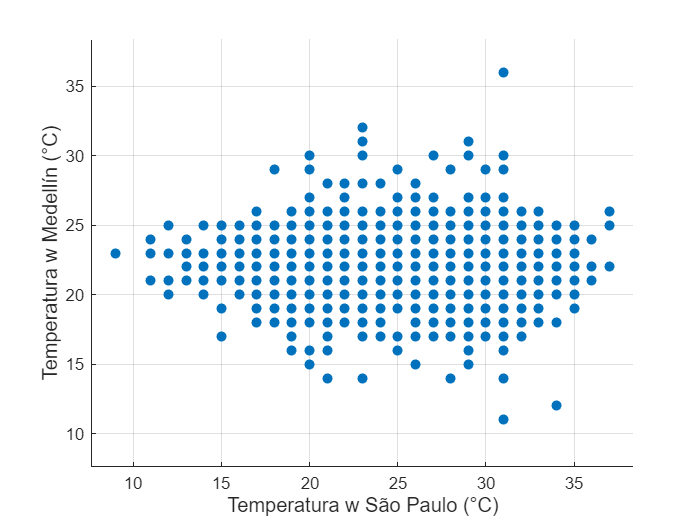

dates_cm = colombia_medellin.date;
dates_bs = brazil_saopaulo.date;
maximums_cm = colombia_medellin.max_temp;
maximums_bs = brazil_saopaulo.max_temp;

% Find common dates between the two datasets
[common_dates, idx_cm, idx_bs] = intersect(dates_cm, dates_bs);

% Extract temperature data only for matching dates
maximums_cm = maximums_cm(idx_cm);
maximums_bs = maximums_bs(idx_bs);

min_temp = min([maximums_bs; maximums_cm]);
max_temp = max([maximums_bs; maximums_cm]);

padding = 0.05 * (max_temp - min_temp);
min_limit = min_temp - padding;
max_limit = max_temp + padding;

figure(9);

scatter(maximums_bs, maximums_cm, 'filled')
xlim([min_limit max_limit]);
ylim([min_limit max_limit]);

ylabel('Temperatura w Medellín (°C)', 'FontSize', 12);
xlabel('Temperatura w São Paulo (°C)', 'FontSize', 12);
grid on;

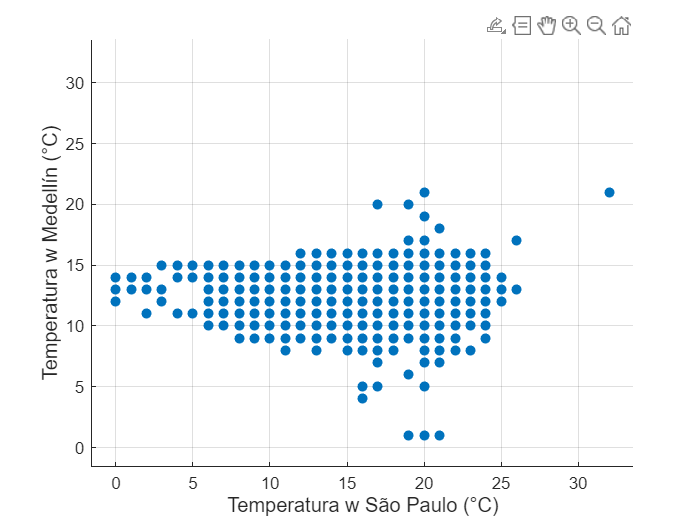

dates_cm = colombia_medellin.date;
dates_bs = brazil_saopaulo.date;
minimums_cm = colombia_medellin.min_temp;
minimums_bs = brazil_saopaulo.min_temp;

% Find common dates between the two datasets
[common_dates, idx_cm, idx_bs] = intersect(dates_cm, dates_bs);

% Extract temperature data only for matching dates
minimums_cm = minimums_cm(idx_cm);
minimums_bs = minimums_bs(idx_bs);

min_temp = min([minimums_bs; minimums_cm]);
max_temp = max([minimums_bs; minimums_cm]);

padding = 0.05 * (max_temp - min_temp);
min_limit = min_temp - padding;
max_limit = max_temp + padding;

figure(9);

scatter(minimums_bs, minimums_cm, 'filled')
xlim([min_limit max_limit]);
ylim([min_limit max_limit]);

ylabel('Temperatura w Medellín (°C)', 'FontSize', 12);
xlabel('Temperatura w São Paulo (°C)', 'FontSize', 12);
grid on;